# ESERCITAZIONE___20/04/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili Simboliche

syms h1 h2 h3 dh1 dh2 dh3 u1 u2 w real

#### Parametri

A1 = 1;
A2 = 1;
A3 = 1;

a12 = 0.6;
a23 = 0.4;
a2 = 0.3;
a3 = 0.25;

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [h1;
     h2;
     h3];

% Uscita
y = x;

% Dimensioni
n = size(x,1);
m = size(u,1);
v = size(y,1);

#### Modello Dinamico Non lineare

eq_1_sym = A1*dh1 == u1 - a12*sqrt(h1-h2);
eq_2_sym = A2*dh2 == a12*sqrt(h1-h2) - a23*sqrt(h2-h3) - a2*sqrt(h2);
eq_3_sym = A3*dh3 == u2 + a23*sqrt(h2-h3) - a3*sqrt(h3);

eqs_sym = [eq_1_sym;
           eq_2_sym;
           eq_3_sym];

% dx/dt
f = [dh1;
     dh2;
     dh3];

% y
g = y;

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

#### Punto di equilibrio x*

x_star = [3.274;
          2;
          1.6];

#### Ingressi u1* e u2* che rendono x* un Punto di equilibrio 

eqs_peql = subs([eq_1_sym, eq_3_sym], [dh1, dh2, dh3, h1, h2, h3], [0, 0, 0, 3.274, 2, 1.6]);
u_star = solve(eqs_peql, [u1, u2], "ReturnConditions",true);

u1_star = double(u_star.u1);
u2_star = double(u_star.u2);

u_star = [u1_star;
          u2_star]

u_star =     0.6772
    0.0632


#### Modello Linearizzato in x*, u*

f_sym = solve(eqs_sym, [dh1, dh2, dh3], "ReturnConditions",true);

f = [f_sym.dh1;
     f_sym.dh2;
     f_sym.dh3];

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x;u], [x_star;u_star]));
B = double(subs(B_sym, [x;u], [x_star;u_star]));
C = double(subs(C_sym, [x;u], [x_star;u_star]));
D = double(subs(D_sym, [x;u], [x_star;u_star]));

sys = ss(A, B, C, D)


sys =
 
  A = 
            x1       x2       x3
   x1  -0.2658   0.2658        0
   x2   0.2658  -0.6881   0.3162
   x3        0   0.3162   -0.415
 
  B = 
       u1  u2
   x1   1   0
   x2   0   0
   x3   0   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


#### Verifica Stabilità, Raggiungibilità e Osservabilità

Stabilità

autovalori = eig(A);
parte_reale = real(autovalori);

if all(parte_reale < 0)
    disp('Il sistema è LOCALMENTE ASINTOTICAMENTE STABILE in x*'); disp('Autovalori della matrice Jacobiana A in x*:'); disp(autovalori);
    
elseif any(parte_reale > 0)
    disp('Il sistema è INSTABILE in x*'); disp('Autovalori della matrice Jacobiana A in x*:'); disp(autovalori);
    
else
    % Caso con max(parte_reale) == 0
    disp('Caso critico (autovalori con parte reale nulla). L''analisi lineare con l''approccio agli autovalori è INCONCLUDENTE in x*.'); disp('Autovalori della matrice Jacobiana A in x*:'); disp(autovalori);
end

Il sistema è LOCALMENTE ASINTOTICAMENTE STABILE in x*
Autovalori della matrice Jacobiana A in x*:
   -0.9690
   -0.3390
   -0.0609



Raggiungibilità

if rank(ctrb(A,B)) == n
    disp('Il sistema linearizzato è completamente raggiungibile');
else
    disp('Il sistema linearizzato NON è completamente raggiungibile');
end

Il sistema linearizzato è completamente raggiungibile


Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema linearizzato è completamente osservabile');
else
    disp('Il sistema linearizzato NON è completamente osservabile');
end

Il sistema linearizzato è completamente osservabile


## 2)  CONTROLLO STABILIZZANTE MEDIANTE APPROCCIO ALLA LYAPUNOV (LMI)

#### Specifiche

% Condizione iniziale
h0 = [0.3;
      0.2;
      0.1];

% Riferimento
href = [0.5;
        0.4];

#### Sintesi LMI con CVX

cvx_clear;
cvx_begin sdp quiet
cvx_precision high

    variable Q(n,n) symmetric
    variable L(m,n)

    minimize(0);

    subject to
    Q >= (1e-6)*eye(n); % Q deve essere semidefinito positivo
    A*Q + Q*A' + B*L + L'*B' <= (1e-6)*eye(n); 
cvx_end;

K_LMI = -L/Q

K_LMI =     0.2260    0.5389   -0.0185
   -0.0011    0.6404    0.0733


#### Compensazione del Guadagno

sys_cl_LMI = ss((A-B*K_LMI), B, C(1:2, :), D(1:2, 1:2));

gain_lmi = dcgain(sys_cl_LMI);

N = pinv(gain_lmi)

N =     0.5073    0.2328
   -0.4115    1.3868


#### Verifica Simulazione

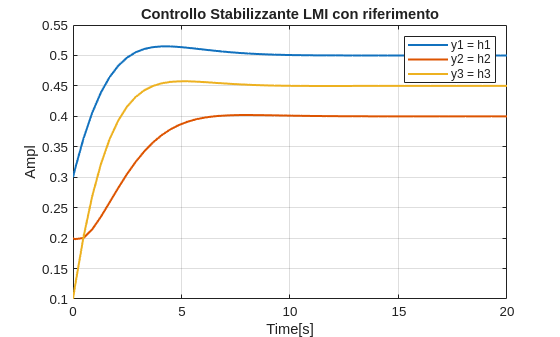

% Plot MATLAB
out = sim('LMI.slx');
y1 = out.y1.Data;
y2 = out.y2.Data;
y3 = out.y3.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
hold on
plot(time, y2, "LineWidth", 1.5);
hold on
plot(time, y3, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = h1', 'y2 = h2', 'y3 = h3');
title('Controllo Stabilizzante LMI con riferimento');

## 3)  CONTROLLO LQR CON AZIONE INTEGRALE

#### Specifiche

h2ref = 2.8;

Ts = 1;
alpha = 4/Ts;

#### Sistema Aumentato

C_LQR = [0, 1, 0];

A_aug = [A, zeros(n,1);
         -C_LQR, 0];

eig(A_aug)

ans =          0
   -0.9690
   -0.0609
   -0.3390



n_aug = size(A_aug,1);

A_hat = A_aug + alpha*eye(n_aug);

eig(A_hat)

ans =     4.0000
    3.0310
    3.9391
    3.6610



B_aug = [B;
         zeros(1,m)];

C_aug = [eye(n) zeros(n,1)];

sys_aug = ss(A_hat, B_aug, C_aug, D)


sys_aug =
 
  A = 
           x1      x2      x3      x4
   x1   3.734  0.2658       0       0
   x2  0.2658   3.312  0.3162       0
   x3       0  0.3162   3.585       0
   x4       0      -1       0       4
 
  B = 
       u1  u2
   x1   1   0
   x2   0   0
   x3   0   1
   x4   0   0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


#### Sintesi LQR

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n),20)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0    20


R = eye(m)

R =      1     0
     0     1


K_LQR = lqr(A_aug, B_aug, Q, R)

K_LQR =     1.2843    3.1771    0.5972   -2.9032
    0.5972    3.6912    1.3598   -3.4017



K_LQR_x = K_LQR(:, 1:n)

K_LQR_x =     1.2843    3.1771    0.5972
    0.5972    3.6912    1.3598



K_LQR_i = K_LQR(:, n+1:end)

K_LQR_i =    -2.9032
   -3.4017


#### Verifica Simulazione

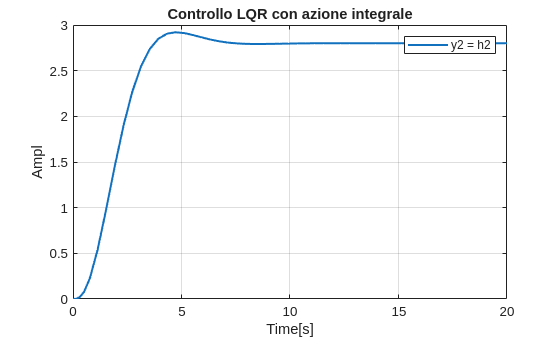

% Plot MATLAB
out = sim('LQR.slx');
y2_lqr = out.y2.Data;
time = out.y2.Time;

figure
plot(time, y2_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y2 = h2');
title('Controllo LQR con azione integrale');

## 4)  CONTROLLO H-INF

rho = 0.1;

z = [h1;
     h2;
     h3;
     rho*u1;
     rho*u2];

n_z = size(z,1);


eq_2_sym_w = A2*dh2 == a12*sqrt(h1-h2) - a23*sqrt(h2-h3) - a2*sqrt(h2) + w;

#### Modello linearizzato con disturbo w 

eqs_sym_w = [eq_1_sym;
             eq_2_sym_w;
             eq_3_sym];

f_sym_w = solve(eqs_sym_w, [dh1, dh2, dh3], "ReturnConditions",true);

f_w = [f_sym_w.dh1;
       f_sym_w.dh2;
       f_sym_w.dh3];

A_sym_w = jacobian(f_w,x);
Bu_sym_w = jacobian(f_w,u);
Bw_sym_w = jacobian(f_w,w);
C_sym_w = jacobian(g,x);
Du_sym_w = jacobian(g,u);
Dw_sym_w = jacobian(g,w);

A_w = double(subs(A_sym_w, [x; u; w], [x_star; u_star; 0]));
Bu_w = double(subs(Bu_sym_w, [x; u; w], [x_star; u_star; 0]));
Bw_w = double(subs(Bw_sym_w, [x; u; w], [x_star; u_star; 0]));
C_w = double(subs(C_sym_w, [x; u; w], [x_star; u_star; 0]));
Du_w = double(subs(Du_sym_w, [x; u; w], [x_star; u_star; 0]));
Dw_w = double(subs(Dw_sym_w, [x; u; w], [x_star; u_star; 0]));

Cy = C_w;
By = [Bw_w, Bu_w];
Dy = [Dw_w, Du_w];

sys_w = ss(A_w, By, C_w, Dy)


sys_w =
 
  A = 
            x1       x2       x3
   x1  -0.2658   0.2658        0
   x2   0.2658  -0.6881   0.3162
   x3        0   0.3162   -0.415
 
  B = 
       u1  u2  u3
   x1   0   1   0
   x2   1   0   0
   x3   0   0   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
 
Continuous-time state-space model.


#### Matrici per l'uscita di prestazione z

Cz = [C;              % eye(3)
      zeros(m,n)]    % zeros(2,3)

Cz =      1     0     0
     0     1     0
     0     0     1
     0     0     0
     0     0     0



Dzu = [zeros(n,m);
      rho*eye(2,m)]

Dzu =          0         0
         0         0
         0         0
    0.1000         0
         0    0.1000


Dzw = zeros(n_z,1)

Dzw =      0
     0
     0
     0
     0


Dz = [Dzw Dzu]

Dz =          0         0         0
         0         0         0
         0         0         0
         0    0.1000         0
         0         0    0.1000


#### Plant generalizzato P

C_gen = [Cz;
         Cy];

D_gen = [Dz;
         Dy];

B_gen = By;

A_gen = A_w;

P = ss(A_gen, B_gen, C_gen, D_gen)


P =
 
  A = 
            x1       x2       x3
   x1  -0.2658   0.2658        0
   x2   0.2658  -0.6881   0.3162
   x3        0   0.3162   -0.415
 
  B = 
       u1  u2  u3
   x1   0   1   0
   x2   1   0   0
   x3   0   0   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
   y4   0   0   0
   y5   0   0   0
   y6   1   0   0
   y7   0   1   0
   y8   0   0   1
 
  D = 
        u1   u2   u3
   y1    0    0    0
   y2    0    0    0
   y3    0    0    0
   y4    0  0.1    0
   y5    0    0  0.1
   y6    0    0    0
   y7    0    0    0
   y8    0    0    0
 
Continuous-time state-space model.


#### Sintesi H-INF

nmeas = v;  % numero uscite misurate (dimensione di y)
ncont = m; % numero di ingressi (dimensione di u)

[K_HINF, CL, gamma, info] = hinfsyn(P, nmeas, ncont);

#### Verifica Simulazione

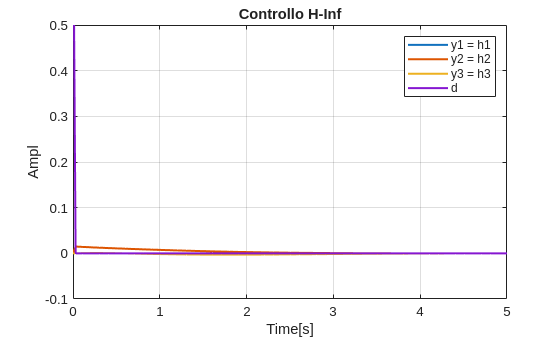

% Plot MATLAB
out = sim('HINF.slx');
y_hinf = out.y.Data;
d = out.d.Data;
time = out.y.Time;

figure
plot(time, y_hinf, "LineWidth", 1.5);
grid on
hold on 
plot(time, d, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = h1', 'y2 = h2', 'y3 = h3', 'd');
title('Controllo H-Inf');
hold off

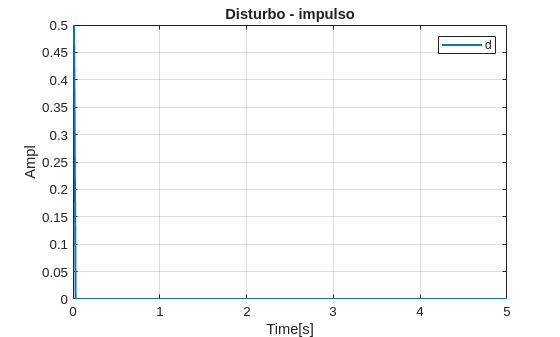

plot(time, d, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('d');
title('Disturbo - impulso');

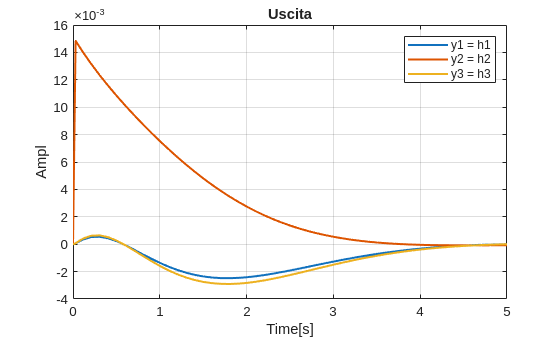

plot(time, y_hinf, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = h1', 'y2 = h2', 'y3 = h3');
title('Uscita');